Definindo as constante

clear all
m = 188.6 ; % Massa do ROV
I_z = 40.50 ; %Momento de inércia ao redor Z
m_u = 450.87; %Massa virtual na direção X
m_v = 558.92; %Massa virtual na direção Y
I_r = 239.44; %Momento virtual ao redor de Z



Coeficiente de arrasto hidrodinâmicos

K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

Velocidades iniciais constante

U = 0;
V = 0;
R = 0;

Vetor de tempo

t = 0:0.01:60;

Condição inicial

q0 = [U;V;0;R];

Simulação não linear

[t,q] = ode45(@sistema,t,q0);

Construções das matrizes linearizadas


A = [ -(K_u/m_u)-((2*abs(U)*K_uu)/m_u), ((abs(R)*m_v)/m_u), 0, ((abs(V)*m_v)/m_u);
    -((abs(R)*m_u)/m_v), -(K_v/m_v)-((2*abs(V)*K_vv)/m_v), 0, -((abs(U)*m_u)/m_v);
    0, 0, 0, 1; 
    ((m_u-m_v)*abs(V)/I_r), ((m_u-m_v)*abs(U)/I_r), 0, -(K_r/I_r)-((2*abs(R)*K_rr)/I_r)];


B = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r;
     0, 0, 0];


C = eye(4,4);

D = zeros(4,3);


Criação do espaço de estados

sl = ss(A, B, C, D);
pz = pzmap(sl);

Entradas do sistema linear

u1 = zeros(size(t));
u2 = zeros(size(t));
u3 = zeros(size(t));

for i = 1:1:500
    u1(i) = 0;
 
end

for i = 501:1:6001
    u1(i) = 0;
   
end

for i = 1:1:6001
    u2(i) = 5*sin(2*pi()*0.1*t(i));
end

Vetor de entradas

u = [u1,u2,u3];

Condições iniciais

x0 = [0; 0; 0; 0];

Simulação linear

[y,x] = lsim(sl, u, t, x0);
y = transpose(y);


Cálculo das saídas considerando a posição de equilíbrio e os desvios incrementais 


q2=  U + y(1,:);

q4 = V + y(2,:);

q_5 = zeros(size(t));
for i = 1:1:length(t)
    q_5(i) = R*t(i) + y(3,i);
end
q6 = R + y(4,:);


plotagem dos gráficos

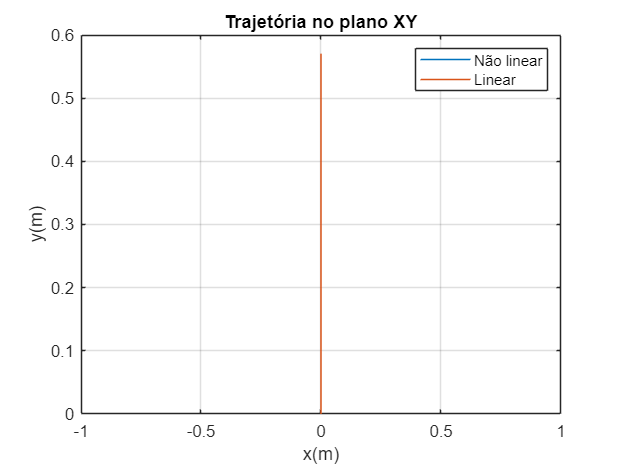

%plot trajetória

%não linear
vel_nl_x = q(:,1);
vel_nl_xT = transpose(vel_nl_x);
vel_nl_y = q(:,2);
vel_nl_yT = transpose(vel_nl_y);
Vtx1_nl = cos(q(:,3))*vel_nl_xT - sin(q(:,3))*vel_nl_yT;
Vty1_nl = sin(q(:,3))*vel_nl_xT + cos(q(:,3))*vel_nl_yT;
Vtx_nl = diag(Vtx1_nl);
Vty_nl = diag(Vty1_nl);
Tjx_nl = cumtrapz(t, Vtx_nl);
Tjy_nl = cumtrapz(t, Vty_nl);

%linear
Vtx1 = cos(q_5)*q2 - sin(q_5)*q4;
Vty1 = sin(q_5)*q2 + cos(q_5)*q4;
Vtx = diag(Vtx1);
Vty = diag(Vty1);
Tjx = cumtrapz(t, Vtx);
Tjy = cumtrapz(t, Vty);


plot([Tjx_nl, Tjx], [Tjy_nl, Tjy])
grid on
xlabel 'x(m)'
ylabel 'y(m)'
legend('Não linear', 'Linear')
title 'Trajetória no plano XY'

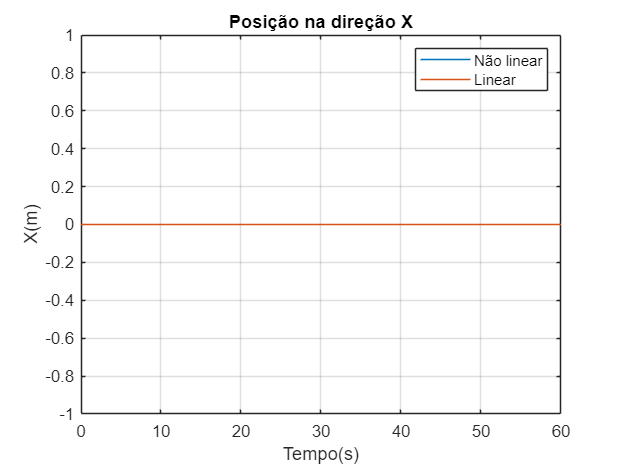


plot(t,Tjx_nl,t,Tjx)
grid on
title 'Posição na direção X'
xlabel('Tempo(s)')
ylabel('X(m)')
legend('Não linear', 'Linear')

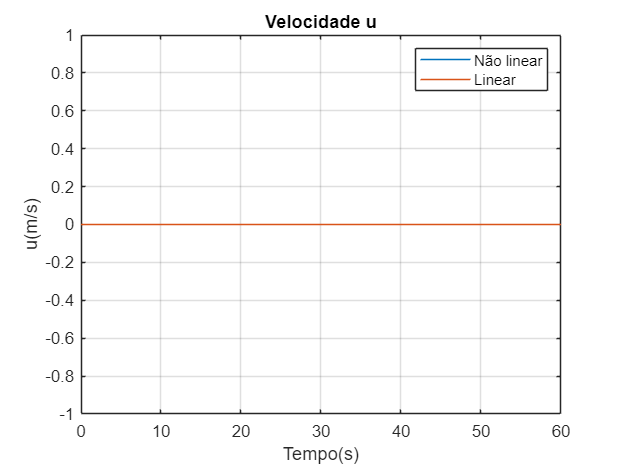



plot(t,q(:,1),t,q2)
grid on
title 'Velocidade u'
xlabel 'Tempo(s)'
ylabel 'u(m/s)'
legend ('Não linear', 'Linear')

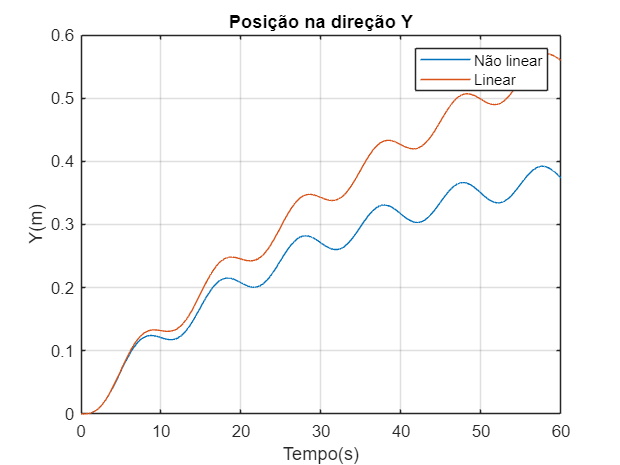




plot(t,Tjy_nl,t,Tjy)
grid on
title 'Posição na direção Y'
xlabel 'Tempo(s)'
ylabel 'Y(m)'
legend ('Não linear', 'Linear')

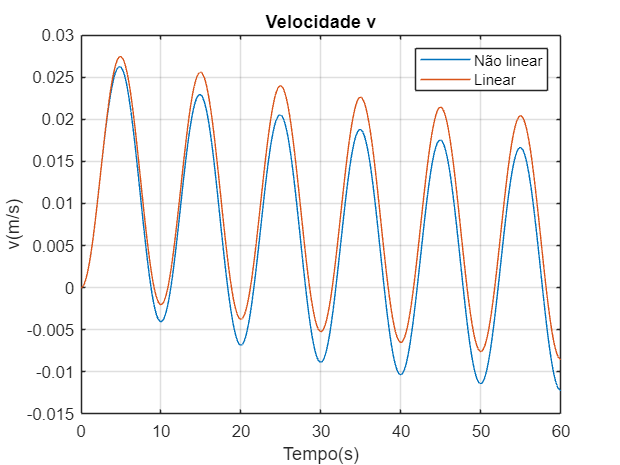


plot(t,q(:,2),t,q4)
grid on
title 'Velocidade v'
xlabel 'Tempo(s)'
ylabel 'v(m/s)'
legend ('Não linear', 'Linear')

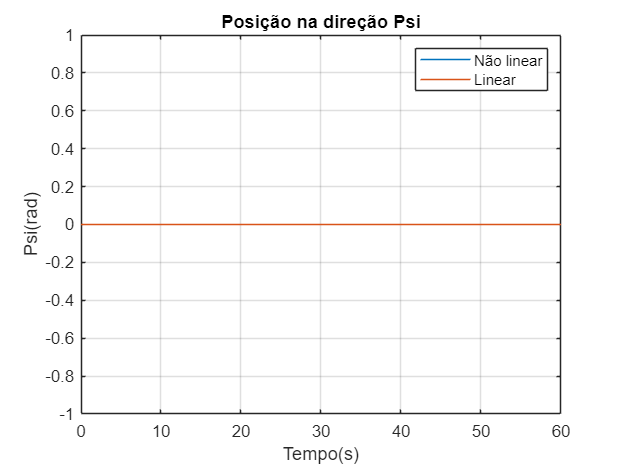



plot(t,q(:,3),t,q_5)
grid on
title 'Posição na direção Psi'
xlabel 'Tempo(s)'
ylabel 'Psi(rad)'
legend ('Não linear', 'Linear')

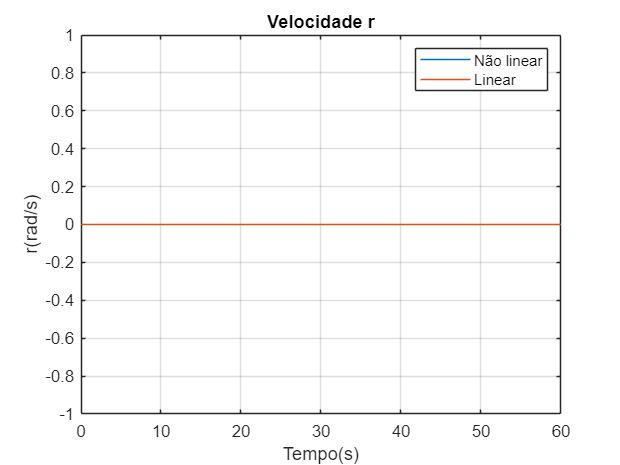


plot(t,q(:,4),t,q6)
grid on
title 'Velocidade r'
xlabel 'Tempo(s)'
ylabel 'r(rad/s)'
legend ('Não linear', 'Linear')

Sistema não linear

function dqdt = sistema(t,q)
m_u = 450.87;
m_v = 558.92; 
I_r = 239.44;
K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

U = 0;
V = 0;
R = 0;

if (t<5) 
    F_x = -m_v*abs(V)*abs(R) + K_u*abs(U) + K_uu*abs(U)*abs(U);
else
    F_x = -m_v*abs(V)*abs(R) + K_u*abs(U) + K_uu*abs(U)*abs(U);
end

F_y = m_u*abs(U)*abs(R) + K_v*abs(V)+ K_vv*abs(V)*abs(V) + 5*sin(2*pi()*0.1*t);

T_r = (m_v-m_u)*abs(U)*abs(V) +K_r*abs(R) + K_rr*abs(R)*abs(R);

dqdt = [(m_v/m_u)*q(2,:)*q(4,:)-(K_u/m_u)*q(1,:)-(K_uu/m_u)*q(1,:)*abs(q(1,:))+ (F_x/m_u);

       -(m_u/m_v)*q(1,:)*q(4,:) - (K_v/m_v)*q(2,:) - (K_vv/m_v)*q(2,:)* abs(q(2,:))+ (F_y/m_v);

       q(4,:);

       ((m_u-m_v)/I_r)*q(1,:)*q(2,:) - (K_r/I_r)*q(4,:) - (K_rr/I_r)*q(4,:)*abs(q(4,:)) + (T_r/I_r)];
end

